# **Matlab案例代码解析**

## 7. 神经网络和机器学习案例

### 7.4 机器学习

#### 7.4.2 ELM回归

clear; clc;
% 导入数据
load data\data_regression.mat
% 随机生成训练集、测试集
k = randperm(size(input,1));
% 训练集—1900个样本
P_train = input(k(1 : 1900), :)';
T_train = output(k(1 : 1900));
% 测试集—100个样本
P_test = input(k(1901 : 2000),:)';
T_test = output(k(1901 : 2000));
%% ELM
% 归一化
% 训练集
[Pn_train, inputps] = mapminmax(P_train, -1, 1);
Pn_test = mapminmax('apply', P_test, inputps);
% 测试集
[Tn_train, outputps] = mapminmax(T_train, -1, 1);
% ELM创建/训练
[IW, B, LW, TF, TYPE] = ELMtrain(Pn_train, Tn_train, 20, 'sig', 0);
% ELM仿真测试
Tn_sim = ELMpredict(Pn_test, IW, B, LW, TF, TYPE);
% 反归一化
T_sim = mapminmax('reverse', Tn_sim, outputps);
%% 结果对比
% 均方误差
E = mse(T_sim - T_test);
disp(['军方误差：', num2str(E)]);

军方误差：5.3283e-05


% 决定系数
N = length(T_test);
R2 = (N*sum(T_sim .* T_test) - sum(T_sim) * sum(T_test))^2 / ...
         ((N*sum((T_sim) .^ 2) - (sum(T_sim))^2) * (N*sum((T_test) .^2 ) - (sum(T_test))^2));
disp(['决定系数：', num2str(R2)]);

决定系数：1


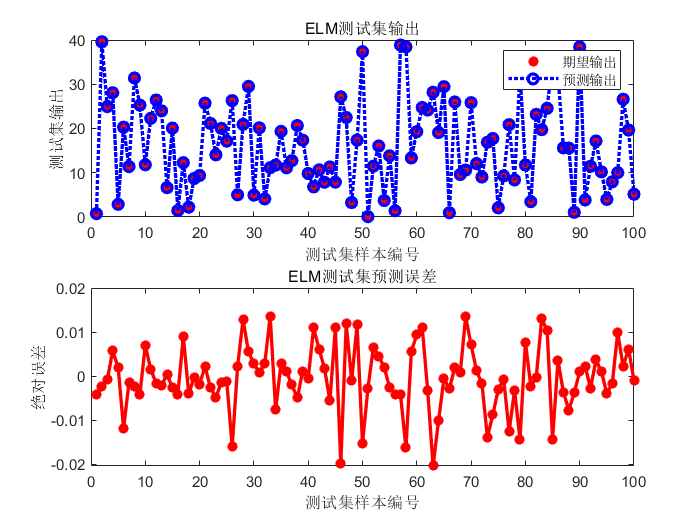

% 绘图
subplot(2, 1, 1)
plot(T_test, 'r*', 'LineWidth', 2)
hold on
plot(T_sim, 'b:o', 'LineWidth', 2)
hold off
xlabel('测试集样本编号')
ylabel('测试集输出')
title('ELM测试集输出')
legend('期望输出', '预测输出')
subplot(2, 1, 2)
plot(T_test - T_sim, 'r-*', 'LineWidth', 2)
xlabel('测试集样本编号')
ylabel('绝对误差')
title('ELM测试集预测误差')

function [IW, B, LW, TF, TYPE] = ELMtrain(P, T, N, TF, TYPE)
%{
Input:
    P   - Input Matrix of Training Set  (R*Q)
    T   - Output Matrix of Training Set (S*Q)
    N   - Number of Hidden Neurons (default = Q)
    TF  - Transfer Function:
          'sig' for Sigmoidal function (default)
          'sin' for Sine function
          'hardlim' for Hardlim function
    TYPE - Regression (0, default) or Classification (1)
Output:
    IW  - Input Weight Matrix (N*R)
    B   - Bias Matrix  (N*1)
    LW  - Layer Weight Matrix (N*S)
%}
[R, Q] = size(P);
if TYPE  == 1
    T  = ind2vec(T);
end
% Randomly Generate the Input Weight Matrix
IW = rand(N, R) * 2 - 1;
% Randomly Generate the Bias Matrix
B = rand(N, 1);
BiasMatrix = repmat(B, 1, Q);
% Calculate the Layer Output Matrix H
tempH = IW * P + BiasMatrix;
switch TF
    case 'sig'
        H = 1 ./ (1 + exp(-tempH));
    case 'sin'
        H = sin(tempH);
    case 'hardlim'
        H = hardlim(tempH);
end
% Calculate the Output Weight Matrix
LW = pinv(H') * T';
end


function Y = ELMpredict(P, IW, B, LW, TF, TYPE)
%{
Input:
    P   - Input Matrix of Training Set  (R*Q)
    IW  - Input Weight Matrix (N*R)
    B   - Bias Matrix  (N*1)
    LW  - Layer Weight Matrix (N*S)
    TF  - Transfer Function:
          'sig' for Sigmoidal function (default)
          'sin' for Sine function
          'hardlim' for Hardlim function
    TYPE - Regression (0, default) or Classification (1)
Output:
Y   - Simulate Output Matrix (S*Q)
%}
% Calculate the Layer Output Matrix H
Q = size(P, 2);
BiasMatrix = repmat(B, 1, Q);
tempH = IW * P + BiasMatrix;
switch TF
    case 'sig'
        H = 1 ./ (1 + exp(-tempH));
    case 'sin'
        H = sin(tempH);
    case 'hardlim'
        H = hardlim(tempH);
end
% Calculate the Simulate Output
Y = (H' * LW)';
if TYPE == 1
    temp_Y = zeros(size(Y));
    for i = 1 : size(Y, 2)
        [~, index] = max(Y(:, i));
        temp_Y(index, i) = 1;
    end
    Y = vec2ind(temp_Y); 
end
end